% change name from code: script_2019_10_iE_all_1
% This script perform summary on twinning stats, look at effect of the
% grain/variant itself.
% The neighboring effect is exmained in another code.

clear;
addChenFunction;

dicPath = uigetdir('D:\WE43_T6_C1\SEM Data\stitched_DIC','pick DIC directory, which contains the stitched DIC data for each stop');

% looks like have to include this part to read the sample name.
[fileSetting,pathSetting] = uigetfile('D:\p\m\DIC_Analysis\setting_for_real_samples\WE43_T6_C1_setting.mat','select setting file which contains sampleName, stopNames, FOVs, translations, etc');
load_settings([pathSetting,fileSetting],'sampleName','cpEBSD','cpSEM','sampleMaterial','stressTensor','strainPauses');

% load previous data and settings
saveDataPath = [uigetdir('D:\WE43_T6_C1\Analysis_by_Matlab_after_realign','choose a path of the saved processed data, or WS, or etc.'),'\'];
saveDataPathInput = saveDataPath;
load([saveDataPath,sampleName,'_traceAnalysis_WS_settings.mat']);
if ~strcmpi(saveDataPath,saveDataPathInput)
    error('Input saveDataPath is different from that saved in setting.mat file. Check files or code.');
end    

% Load from the pre-labeled results: twinMap, sfMap, struCell.  (cToGbDistMap is omitted, as will no longer be used in this code)
% [confirmedLabelFile, confirmedLabelPath] = uigetfile('D:\p\m\DIC_Analysis\*.mat','select the results where twin identification was based on trace dir and strain, for trueTwinMapCell');
% [twinGbIntersectionFile, twinGbIntersectionPath] = uigetfile('D:\p\m\DIC_Analysis\temp_results\*.mat','select the results for twin-grain boundary intersection');

try
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
    dataFile = matfile([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis']);
catch
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
    dataFile = matfile([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted']);
end
% modify / or keep an eye on these settings for the specific sample to analyze  ------------------------------------------------------------------------------------
STOP = {'0','1','2','3','4','5','6','7'};
B=1;    % 0-based B=1.  1-based B=0.
iE_start = 2;   % elongation levels to analyze. 0-based.
iE_stop = 5;

% file name prefixes
f1 = 'WE43_T6_C1_s';
f2 = '_';

debugTF = 0;

%% [data] strain data. Convert into v7.3 for partial loading
%%
clear strainFile;
for iE = iE_start-1:iE_stop
    strainFileName = [dicPath,'\',f2,STOP{iE+B}];
    disp(strainFileName);
    if ~exist([strainFileName,'_v73.mat'],'file')
        load(strainFileName);
        clear('exy_corrected');
        load(strainFileName,'exy_corrected');   % if 'exy_corrected' does not exist, this does not give error, rather, just warning.
        
        if exist('exy_corrected','var')&&(1==exy_corrected)
            disp('================= exy already corrected ! ========================');
            exy_corrected = 1;
        else
            disp('================= exy being corrected here ! =======================');
            exy = -exy;
            exy_corrected = 1;
        end
        % remove bad data points
        exx(sigma==-1) = nan;
        exy(sigma==-1) = nan;
        eyy(sigma==-1) = nan;
        qt_exx = quantile(exx(:),[0.0013,0.9987]); qt_exx(1)=min(-1,qt_exx(1)); qt_exx(2)=max(1,qt_exx(2));
        qt_exy = quantile(exy(:),[0.0013,0.9987]); qt_exy(1)=min(-1,qt_exy(1)); qt_exy(2)=max(1,qt_exy(2));
        qt_eyy = quantile(eyy(:),[0.0013,0.9987]); qt_eyy(1)=min(-1,qt_eyy(1)); qt_eyy(2)=max(1,qt_eyy(2));
        ind_outlier = (exx<qt_exx(1))|(exx>qt_exx(2))|(exy<qt_exy(1))|(exy>qt_exy(2))|(eyy<qt_eyy(1))|(eyy>qt_eyy(2));
        exx(ind_outlier) = nan;
        exy(ind_outlier) = nan;
        eyy(ind_outlier) = nan;
        
        outlier_removed = 1;
        save([strainFileName,'_v73.mat'],'outlier_removed','exy_corrected','-v7.3');
        
        myFile = matfile(strainFileName);
        myFields = who(myFile);
        for ii=1:length(myFields)
            save([strainFileName,'_v73.mat'],myFields{ii},'-append','-v7.3');
        end
    else
        disp('v7.3 file already exist');
    end
    strainFile{iE} = matfile([strainFileName,'_v73.mat']);
end

D:\WE43_T6_C1\SEM Data\stitched_DIC\_1


v7.3 file already exist


D:\WE43_T6_C1\SEM Data\stitched_DIC\_2


v7.3 file already exist


D:\WE43_T6_C1\SEM Data\stitched_DIC\_3


v7.3 file already exist


D:\WE43_T6_C1\SEM Data\stitched_DIC\_4


v7.3 file already exist


D:\WE43_T6_C1\SEM Data\stitched_DIC\_5


v7.3 file already exist



%% (0) load data, using SF threshold values to assign active twin system, and make maps
% Load cluster number maps (cleaned).
clusterNumberMapCell = cell(1,length(STOP)-1);
for iE = []                                         %iE_start:iE_stop
    fName_c2t_result = [sampleName,'_s',num2str(STOP{iE+B}),'_cluster_to_twin_result.mat'];
    load([saveDataPath,fName_c2t_result],'clusterNumMapCleaned');
    clusterNumberMapCell{iE} = clusterNumMapCleaned;
end

% Load from the pre-labeled results: twinMapCell, sfMapCell, struCell.  (cToGbDistMapCell is omitted, as will no longer be used in this code)
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'struCell','twinMapCell','trueTwinMapCell','sfMapCell','tNote');
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'trueTwinMapCell');
% trueTwinFile = matfile(fullfile(confirmedLabelPath,confirmedLabelFile));

% load previous twin_gb interaction result
% load(fullfile(twinGbIntersectionPath, twinGbIntersectionFile));

[newVariantFile, newVariantFilePath] = uigetfile('D:\p\m\DIC_Analysis\temp_results\WE43_T6_C1_new_variant_map.mat','select the new result of dividing twin into variants');
load(fullfile(newVariantFilePath,newVariantFile),'struCell','variantMapCleanedCell','trueTwinMapCell');

edge_gIDs = unique([reshape(ID(1,:),[],1); reshape(ID(end,:),[],1); ID(:,1); ID(:,end)]);

**How should twinning be affected by different microstructural parameters?**

**(1) The effect of Schmid factor:  (from script_organized_summary_11)**

um_per_dp = 5*360/4096;    % micron per data point, ~0.43

% Table_1, for grain summaries.
% In order to study:
% for non-twinned grains: (1) strain vs. <basal_SF>, (2) strain vs. gDiameter
% for all grains: counts of twinned & nontwinned vs. gDiameter
% for twinned grains: (1) counts vs. gDiamter, (2) twinAreaFraction vs. gDiameter
variableNames = {'iE','ID','e1','e5','e10','e50','e90','e95','e99','emean',...
    'basal_SF','pm_SF','py_SF','pyII_SF','twin_SF','activeTwin_SF','gDia','twinnedTF','tAF'};
T = cell2table(cell(0,length(variableNames)));
T.Properties.VariableNames = variableNames;

% Table_2, summarize things for each of the 6 possible variant, for all grains
% For twinned variants, vPct vs. variant_SF
% for all variants: counts of twinned & non-twinned vs. variant_SF
variableNames2 = {'iE','ID','iTwin','variant','variant_SF','vActiveTF','vPct','v1_activeTF','basal_SF','twin_SF'};
T2 = cell2table(cell(0,length(variableNames2)));
T2.Properties.VariableNames = variableNames2;

for iE = 2:5
    eEff = effective_strain(strainFile{iE}.exx, strainFile{iE}.exy, strainFile{iE}.eyy);
    
    hW = waitbar(0,['iE=',num2str(iE),' for each grain ...']);
    NW = length(struCell{iE});
    for iS = 1:length(struCell{iE})
        ID_current = struCell{iE}(iS).gID;
        gd = sqrt(4*struCell{iE}(iS).gVol/pi) * um_per_dp;
        vol_t = sum(struCell{iE}(iS).tVol);
        vol_g = struCell{iE}(iS).gVol;
        
        ind_local = ismember(ID, ID_current); %ismember(ID, [ID_current,ID_neighbor]);
        % Make it one data point wider on each side
        indC_min = max(1, find(sum(ind_local, 1), 1, 'first')-1);
        indC_max = min(size(ID,2), find(sum(ind_local, 1), 1, 'last')+1);
        indR_min = max(1, find(sum(ind_local, 2), 1, 'first')-1);
        indR_max = min(size(ID,1), find(sum(ind_local, 2), 1, 'last')+1);
        
        ID_local = ID(indR_min:indR_max, indC_min:indC_max);
        
        % [*] Calculate the max basal Schmid factor of this grain
        ind = find(ID_current==gID);
        euler_current = [gPhi1(ind),gPhi(ind),gPhi2(ind)];
        [abs_schmid_factor, ~, burgersXY] = trace_analysis_TiMgAl(euler_current, [0 0 0], [0 0 0], stressTensor, 'Mg', 'twin');
        basal_SF = max(abs_schmid_factor(1:3,2));
        pm_SF = max(abs_schmid_factor(4:6,2));
        py_SF = max(abs_schmid_factor(7:12,2));
        pyII_SF = max(abs_schmid_factor(13:18,2));
        twin_SF = max(abs_schmid_factor(19:24,2));
        
        %     uniqueBoundary_local = uniqueBoundary(indR_min:indR_max, indC_min:indC_max);
        map_local = eEff(indR_min:indR_max, indC_min:indC_max);
        map_local(ID_local~=ID_current) = nan;
        
        es = [quantile(map_local(:), [0.01, 0.05, 0.1, 0.5, 0.9, 0.95, 0.99]), nanmean(map_local(:))];
        
        % Find if variant is twinned
        activeTS = [];
        for ie = iE_start:iE
            activeTS(ie-iE_start+1,:) = sum(struCell{ie}(iS).cTrueTwin,1);
        end
        activeTS = logical(sum(activeTS,1));
        
        if iE==iE_start
            activeTS_pre = [0 0 0 0 0 0];
        else
            activeTS_pre = [];
            for ie = iE_start:iE-1
                activeTS_pre(ie-iE_start+1,:) = sum(struCell{ie}(iS).cTrueTwin,1);
            end
            activeTS_pre = logical(sum(activeTS_pre,1));
        end
        
        newActiveTS = (activeTS - activeTS_pre)>0;      % --> ---------------------------------> we may choose between all activeSS or newActiveSS
        tSFs = struCell{iE}(iS).tSF;
        [~,SF_order]=ismember(tSFs,sort(tSFs,'descend'));   % find index of ranking of element in array
        
        % determine if this grain is twinned. If twinned, twin_SF = max of active twin ss.  If not twinned, twin_SF = max of twin ss.
        if any(activeTS)
            activeTwin_SF = max(struCell{iE}(iS).tSF(activeTS));
            T = [T; {iE, ID_current, es(1),es(2),es(3),es(4),es(5),es(6),es(7),es(8),...
                basal_SF, pm_SF, py_SF, pyII_SF, twin_SF, activeTwin_SF, gd, true, vol_t/vol_g}];
        else
            activeTwin_SF = nan;
            T = [T; {iE, ID_current, es(1),es(2),es(3),es(4),es(5),es(6),es(7),es(8),...
                basal_SF, pm_SF, py_SF, pyII_SF, twin_SF, activeTwin_SF, gd, false, vol_t/vol_g}];
        end
        
        % ii is the twin system index from 1 to 6.
        [~,idx] = max(struCell{iE}(iS).tSF);
        v1_activeTF = activeTS(idx)>0;
        for iTwin=1:length(activeTS)
            if activeTS(iTwin)>0
                vActiveTF = true;
                T2 = [T2; {iE, ID_current, iTwin, SF_order(iTwin), tSFs(iTwin), vActiveTF, struCell{iE}(iS).tVol(iTwin)/vol_g, v1_activeTF, basal_SF, twin_SF}];
            else
                vActiveTF = false;
                T2 = [T2; {iE, ID_current, iTwin, SF_order(iTwin), tSFs(iTwin), vActiveTF, struCell{iE}(iS).tVol(iTwin)/vol_g, v1_activeTF, basal_SF, twin_SF}];
            end
        end
        if rem(iS,10)==1
            waitbar(iS/NW, hW);
        end
    end
    close(hW);
    
end


% choose which to run
% save(['temp_results/',sanmpleName,'_tableSummary_twinStats_selfEffect.mat'],'T','T2');

load(['temp_results/',sampleName,'_tableSummary_twinStats_selfEffect.mat'],'T','T2');


**Summarize at selected strain level, how many grains contains 1/2/3/4 active twin systems.**

ind = (T2.iE==5)&(T2.vActiveTF==1);
t = T2(ind,:);
unique_IDs = unique(t.ID);
result = histcounts(t.ID,[unique_IDs;inf]);
n1 = sum(result==1)

n1 = 154

n2 = sum(result==2)

n2 = 199

n3 = sum(result==3)

n3 = 4

n4 = sum(result==4)

n4 = 0

**(1.1) For non-twinned grains, we expect higher strain in grains with higher basal Schmid factor.  This is because WE43-T5 has a weak texture, which favors basal slip.**

**For twinned grains, we can also look at how the effective strain -vs- twin_SF.**

disp('=========non-twinned grain, strain vs. basal SF==================================');

=========non-twinned grain, strain vs. basal SF==================================


yLimits = [nan,nan;
    0, 0.03;
    0, 0.04;
    0, 0.07;
    0, 0.12];
for iE = 2:5
    
    %% [*] [Plot] selected strain (e.g., median strain vs. basal_SF)
    ind = (T.iE==iE)&(T.twinnedTF==0);                 % ---------------------------> Select which (twinned or non-twinned) grain
    vx = T.basal_SF(ind);                    % ---------------------------> Select which SF here
    vy = T.emean(ind);                      % ---------------------------> Select strain here
    ylabel_str = 'Grain Average Effective Strain';    % ---------------------------> change name
    title_str = ['Non-twinned grain, iE=',num2str(iE)];
    
    figure;disableDefaultInteractivity(gca);
    plot(vx, vy, '.');
    set(gca,'ylim', yLimits(iE,:),'fontsize',14)
    xlabel('Schmid Factor'); ylabel(ylabel_str);
    title(title_str,'fontweight','normal');
    
    
    % [*] Summarize by [boxplot].
    edges = 0:0.05:0.5;
    
    gv = discretize(vx, edges);
    nGroups = length(edges)-1;
    clear labels;
    for ii = 1:length(edges)-1
        labels{ii} = [num2str(edges(ii)),'-',num2str(edges(ii+1))];
    end
    
    figure;disableDefaultInteractivity(gca);
    boxplot([vy; nan*ones(nGroups,1)], [gv; (1:nGroups)'],'Notch','on');     % sometimes, a group does not have anything. This make sure we have all group variables.
    xlabel('Maximum Basal Schmid Factor'); ylabel(ylabel_str);
    set(gca,'xticklabels',labels,'xticklabelrotation',45,'fontsize',16);
    set(gca,'ylim', yLimits(iE,:));
    title(title_str,'fontweight','normal');
    
    

            **% [1. Plot used for paper, Fig 6a]:  X = (Max Basal) Schmid Factor,  Y = Grain Average Effective Strain,  for Non-twinned Grain**

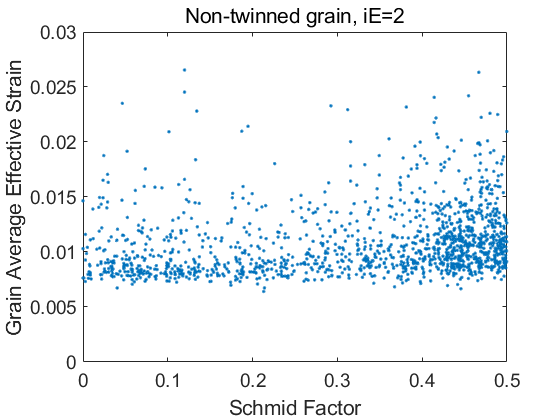

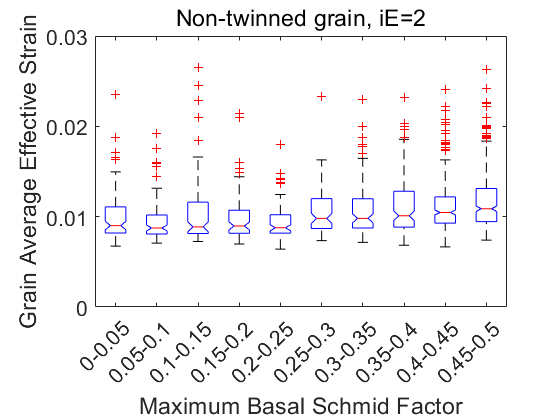

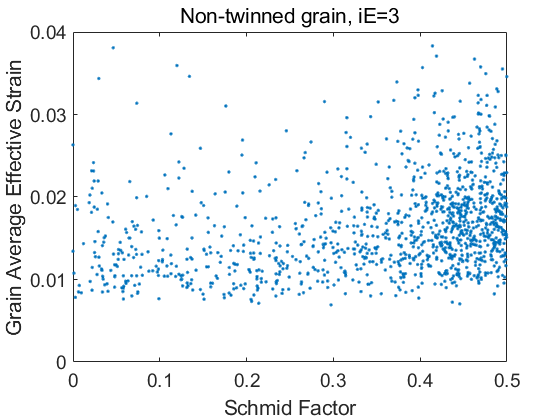

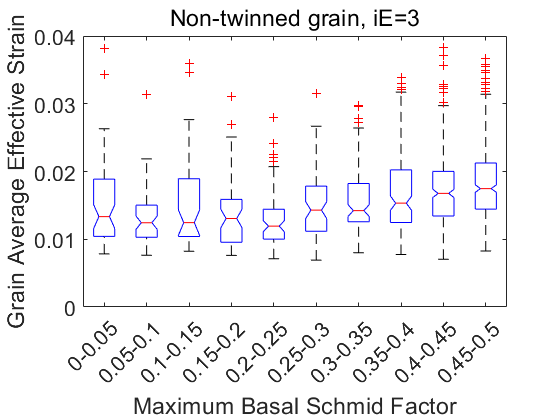

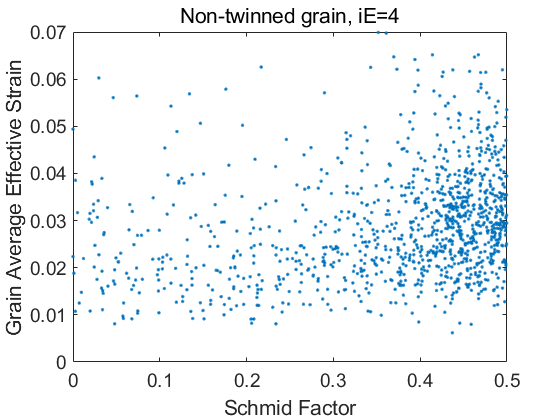

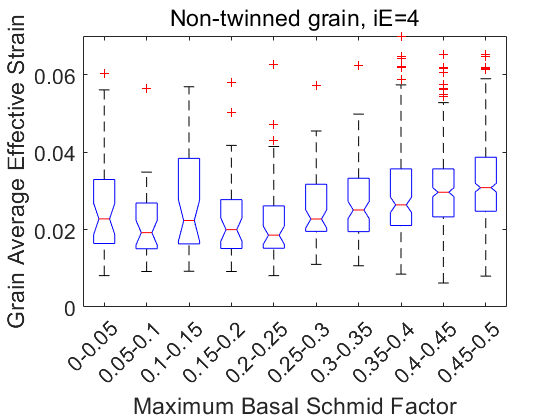

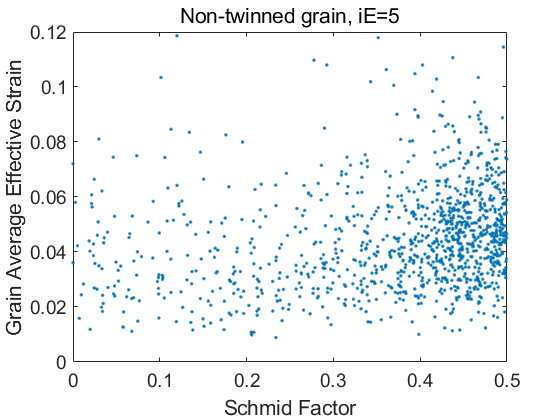

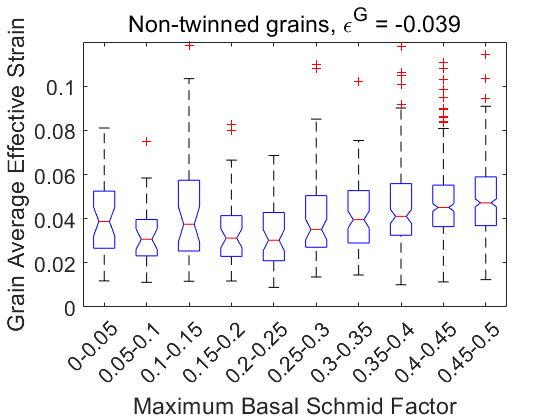

    if iE==5
        title(['Non-twinned grains, \epsilon^G = -0.039'],'fontweight','normal');
    end
end

% Can make titles for paper
% title(['Non-twinned grains, \epsilon^G = -0.039'],'fontweight','normal');  


% Summarize mean effective strain in grains twinned vs. not twinned
disp('=== twinned grains, strain vs. twin SF ====')

=== twinned grains, strain vs. twin SF ====


for iE = 2:5
    
    ind = (T.iE==iE)&(T.twinnedTF==1);                 % ---------------------------> Select which (twinned or non-twinned) grain
    vx = T.twin_SF(ind);                    % ---------------------------> Select which SF here
    vy = T.emean(ind);                      % ---------------------------> Select strain here
    ylabel_str = 'Grain Average Effective Strain';    % ---------------------------> change name
    title_str = ['Twinned grain, iE=',num2str(iE)];
    
    figure;disableDefaultInteractivity(gca);
    plot(vx, vy, '.');
    set(gca,'ylim', yLimits(iE,:),'fontsize',14)
    xlabel('Schmid Factor'); ylabel(ylabel_str);
    title(title_str,'fontweight','normal');
    
    
    % [*] Summarize by [boxplot].
    edges = 0:0.05:0.5;
    
    gv = discretize(vx, edges);
    nGroups = length(edges)-1;
    clear labels;
    for ii = 1:length(edges)-1
        labels{ii} = [num2str(edges(ii)),'-',num2str(edges(ii+1))];
    end
    
    figure;disableDefaultInteractivity(gca);
    boxplot([vy; nan*ones(nGroups,1)], [gv; (1:nGroups)'], 'notch','on');     % sometimes, a group does not have anything. This make sure we have all group variables.
    xlabel('Maximum Twin Schmid Factor'); ylabel(ylabel_str);
    set(gca,'xticklabels',labels,'xticklabelrotation',45,'fontsize',16);
    set(gca,'ylim', yLimits(iE,:));
    title(title_str,'fontweight','normal');
    
    

           ** % [2. Plot used for paper, Fig 6b]: X = (Max Twin) Schmid Factor,  Y = Grain Average Effective Strain,  for Twinned Grain.**

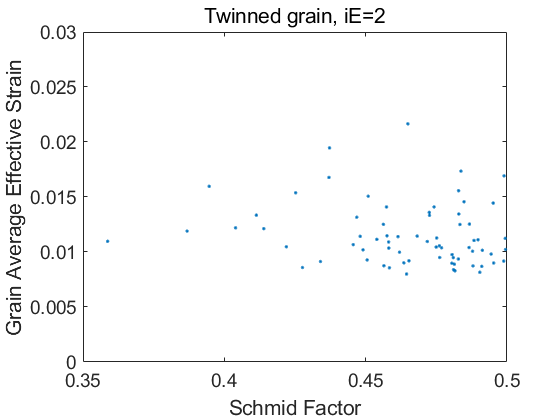

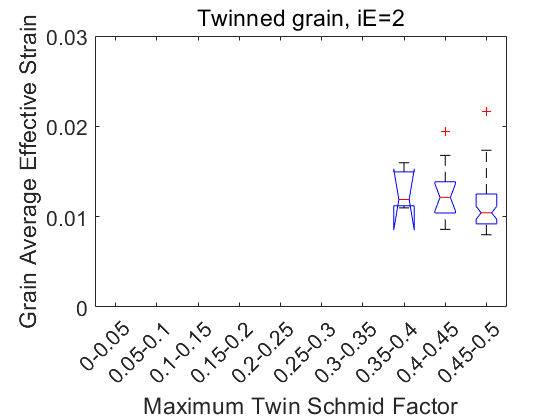

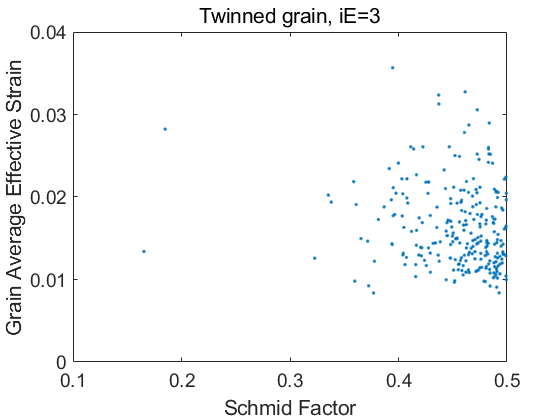

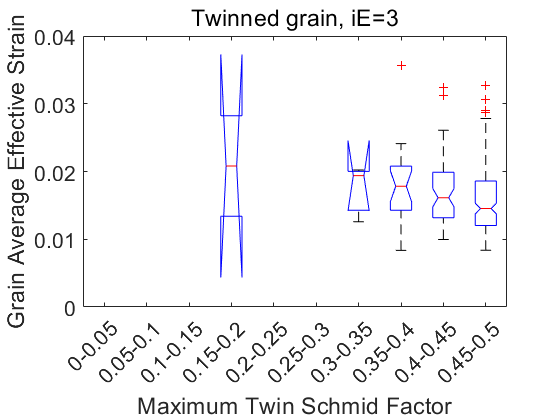

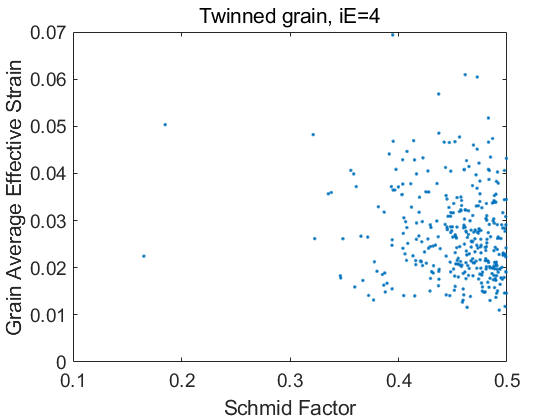

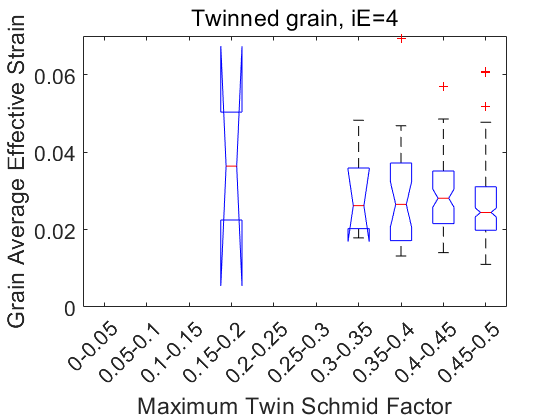

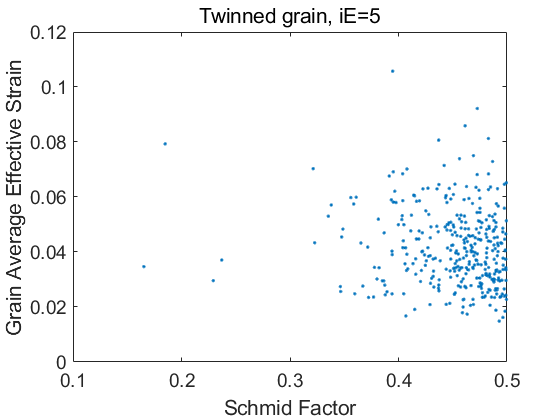

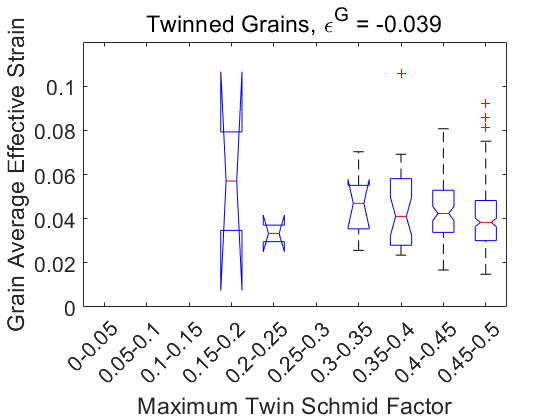

    if iE==5        
        title(['Twinned Grains, \epsilon^G = -0.039'],'fontweight','normal');  
    end
    
end

**The [grain size] does not seem to affect strain in non-twinned grains.**

disp(['=======non-twinned grain, strain vs gDiameter====================================================']);

=======non-twinned grain, strain vs gDiameter====================================================


for iE = 2:5
    ind = (T.iE==iE)&(T.twinnedTF==0);
    vx = T.gDia(ind);
    vy = T.emean(ind);                      % ---------------------------> Select strain here
    ylabel_str = 'Grain Average Effective Strain';    % ---------------------------> change name
    title_str = ['Non-twinned grain, iE=',num2str(iE)];
    
    figure;disableDefaultInteractivity(gca);
    plot(vx, vy, '.');
    set(gca,'ylim', yLimits(iE,:))
    xlabel('Grain Diameter, um'); ylabel(ylabel_str);
    title(title_str,'fontweight','normal');
    
    
    % [*] Summarize by [boxplot].
    edges = [0,60:20:180,400];
    
    gv = discretize(vx, edges);
    nGroups = length(edges)-1;
    clear labels;
    for ii = 1:length(edges)-1
        labels{ii} = [num2str(edges(ii)),'-',num2str(edges(ii+1))];
    end
    
    figure;disableDefaultInteractivity(gca);
    boxplot([vy; nan*ones(nGroups,1)], [gv; (1:nGroups)'],'notch','on');     % sometimes, a group does not have anything. This make sure we have all group variables.
    xlabel(['Grain Diameter (',char(181),'m)']); ylabel(ylabel_str);
    set(gca,'xticklabels',labels,'xticklabelrotation',45,'fontsize',16);
    set(gca,'ylim', yLimits(iE,:));
    title(title_str,'fontweight','normal');
     

            **% [3. Plot used for paper, Fig 9]:  X = Grain Diameter,  Y = Grain Average Effective Strain,  for Non-twinned Grain**

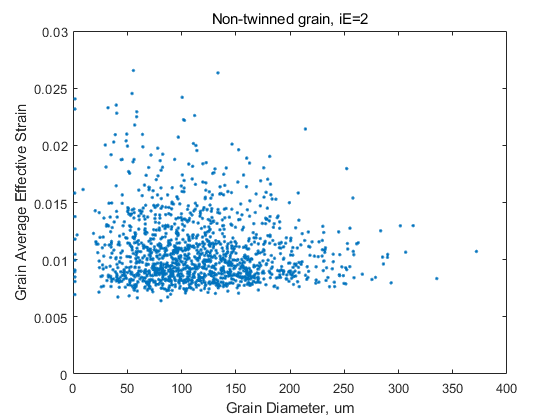

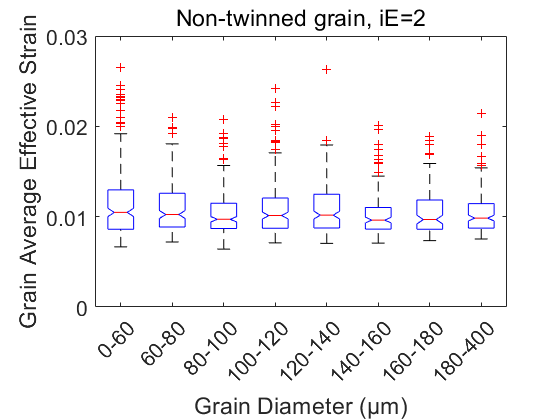

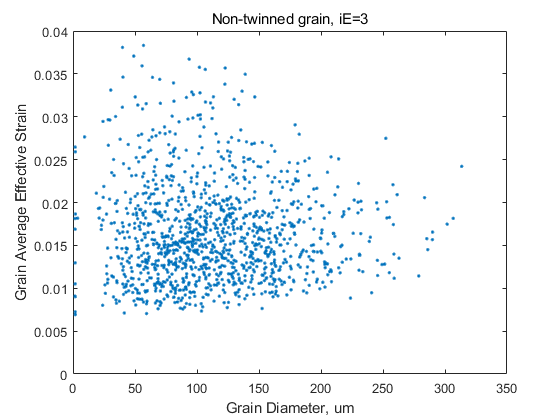

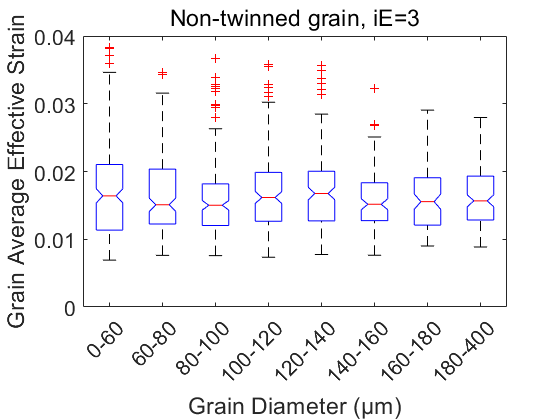

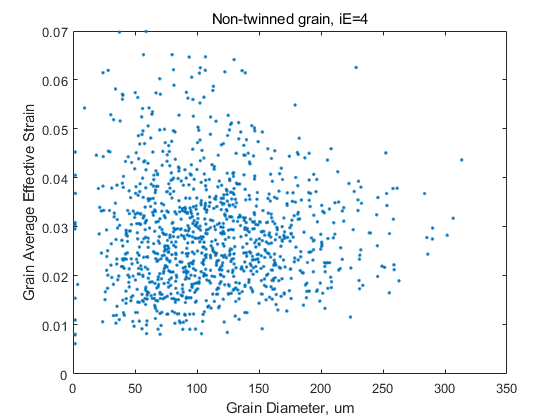

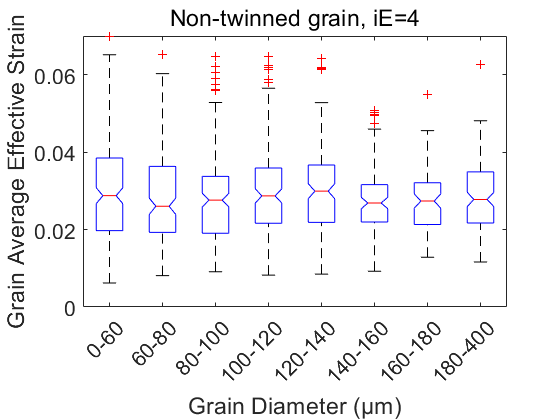

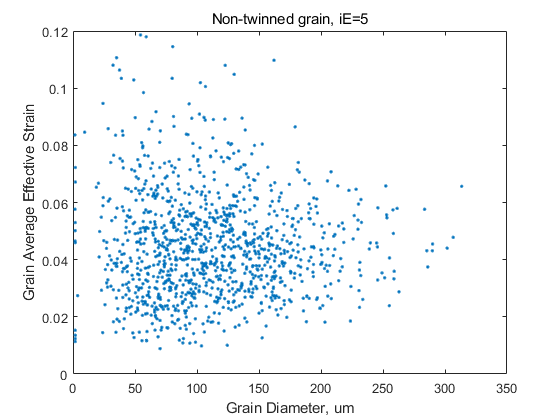

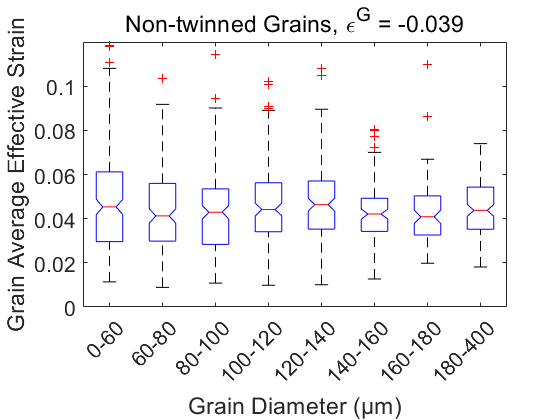

    if iE==5
        title('Non-twinned Grains, \epsilon^G = -0.039')
    end
   
end

**Errorbar plot, summarize the distribution of mean strain of grains vs. gDiameter, at different strain levels**

disp(['====non-twinned grain, strain vs gDia, all iEs====================================================']);

====non-twinned grain, strain vs gDia, all iEs====================================================


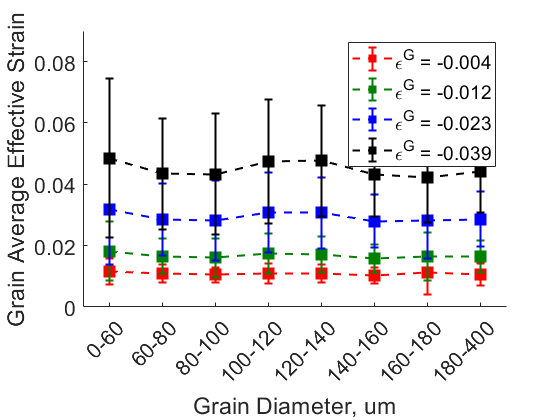

figure;disableDefaultInteractivity(gca);
hold on;
edges = [0,60:20:180,400];
xpos = 60:20:200;
colors = [0 0 0; 1 0 0; 0 0.5 0; 0 0 1; 0 0 0];

for iE = 2:5
    ind = (T.iE==iE)&(T.twinnedTF==0);
    vx = T.gDia(ind);
    vy = T.emean(ind);                      % ---------------------------> Select strain here
    ylabel_str = 'Grain Average Effective Strain';    % ---------------------------> change name
    title_str = ['Non-twinned grain, iE=',num2str(iE)];
    
    % [*] Summarize by [boxplot].
    
    gv = discretize(vx, edges);
    nGroups = length(edges)-1;
    clear labels;
    for ii = 1:length(edges)-1
        labels{ii} = [num2str(edges(ii)),'-',num2str(edges(ii+1))];
    end
    
    for ig=1:nGroups
        stat_mean(ig) = nanmean(vy(gv==ig));
        stat_std(ig) = nanstd(vy(gv==ig));
    end
    
    errorbar(xpos, stat_mean, stat_std,'--s','LineWidth',1.5,'markersize',10,'markerfacecolor',colors(iE,:),'color',colors(iE,:));     % sometimes, a group does not have anything. This make sure we have all group variables.
end
xlabel('Grain Diameter, um'); ylabel(ylabel_str);
set(gca,'xticklabels',labels,'xticklabelrotation',45);
set(gca,'xlim',[50,210],'ylim', [0 0.09],'xTick',xpos,'fontsize',16);
legend('\epsilon^G = -0.004','\epsilon^G = -0.012','\epsilon^G = -0.023','\epsilon^G = -0.039');
title('','fontweight','normal');

**(1.2) For grains that are twinned, look at (all twin variants)**

**(1.2 a) The twin variant area as a fraction of grain size tend to increase with increasing twin variant Schmid factor. **

**This seems to be a step further from [Beyerlein 2011 PhilMag paper], which summarized that as highest twin SF increases, twin area as fraction of grain size increases.**

disp(['========twin variant, size/grain vs SF==============================']);

========twin variant, size/grain vs SF==============================


%% [*] [boxplot] to show twin_area_fraction vs twin_SF
for iE = 2:5
    ind = (T2.iE==iE)&(T2.vActiveTF==1);
    t2 = T2(ind,:);
    edges = 0:0.05:0.5;
    vx = t2.variant_SF;                   % ---------------------------> Select which SF here
    vy = t2.vPct;                      % ---------------------------> Select strain here
    ylabel_str = 'Twin Variant Area Fraction in Grain';    % ---------------------------> change name
    
    figure;disableDefaultInteractivity(gca);
    plot(vx, vy, '.');
    xlabel('Schmid Factor'); ylabel(ylabel_str);
    % set(gca,'ylim',[0 0.1])
    title(['iE=',num2str(iE),', twinned grains'],'fontweight','normal');
    
    gv = discretize(vx, edges);
    nGroups = length(edges)-1;
    clear labels;
    for ii = 1:length(edges)-1
        labels{ii} = [num2str(edges(ii)),'-',num2str(edges(ii+1))];
    end
    figure;disableDefaultInteractivity(gca);
    boxplot([vy; nan*ones(nGroups, 1)], [gv; (1:nGroups)'],'notch','on');
    xlabel('Twin Variant Schmid Factor'); ylabel(ylabel_str)
    set(gca,'xticklabels',labels,'xticklabelrotation',45,'fontsize',15);
    title(['iE=',num2str(iE),', twinned grains'],'fontweight','normal');
    
    

            **[4. Plot used for paper, Fig 5]:  X = Twin Variant Schmid Factor,  Y = Twin Variant Area Fraction in Grain,  for All Twin Variants**

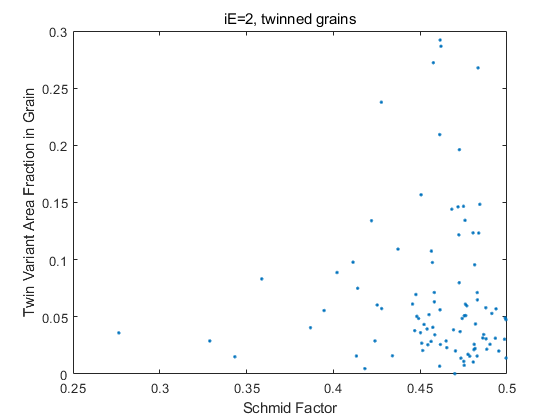

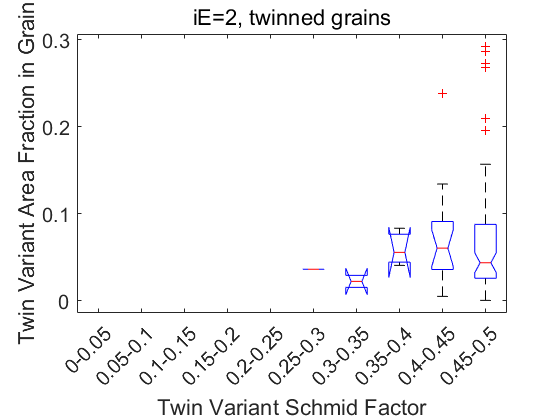

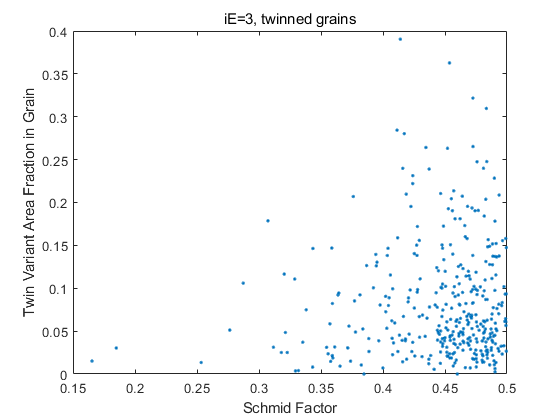

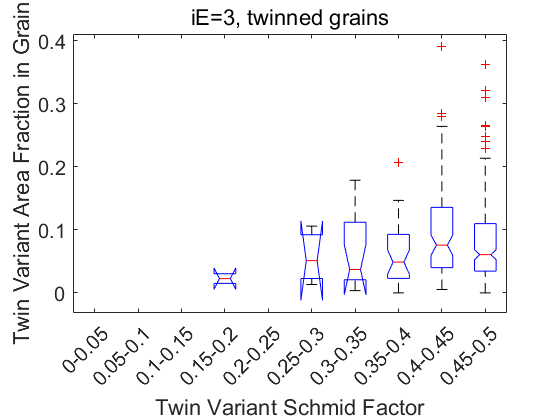

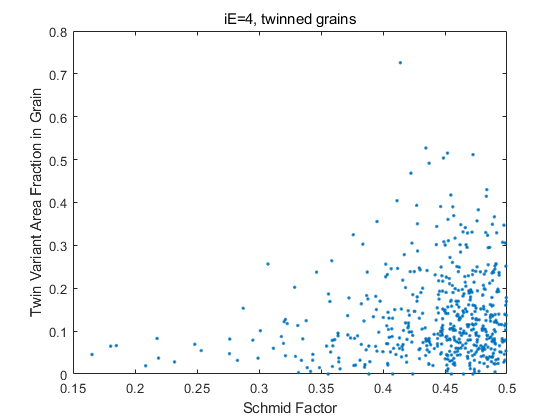

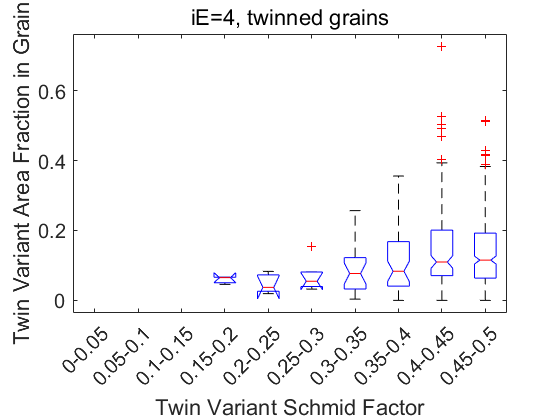

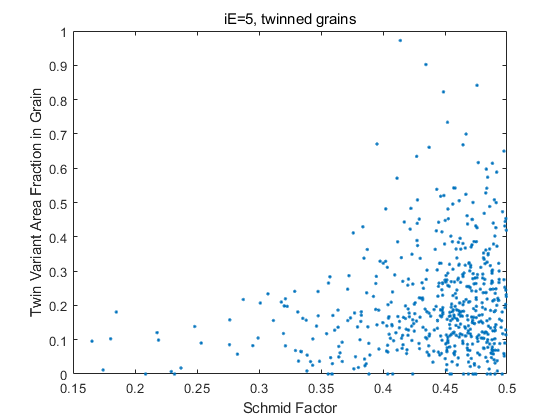

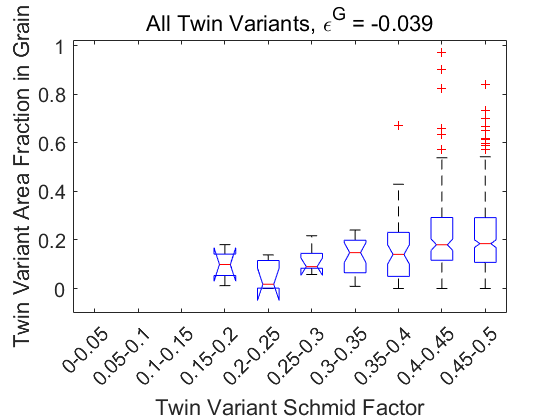

    if iE==5
        title(['All Twin Variants, \epsilon^G = -0.039']);
    end
end

**(1.2 aa) Change x-axis to Variant #.  Twin Variant Area Fraction vs. Variant #: [v1, v2, ..., v6].  This shows easier twinned variant has larger size.  Hard variant, even twinned, the size is still small.**

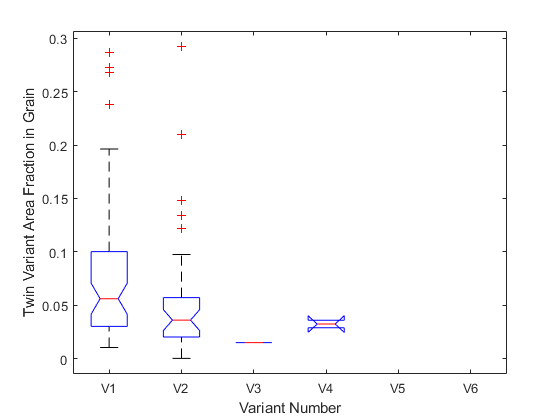

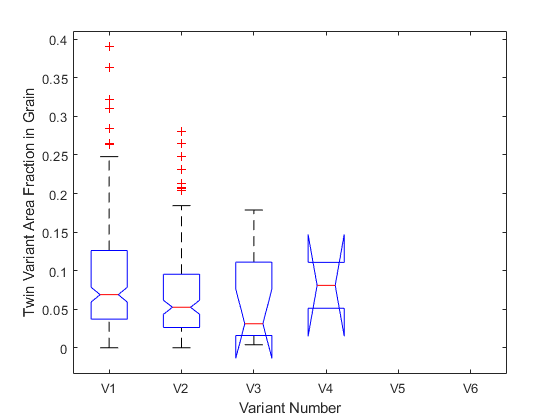

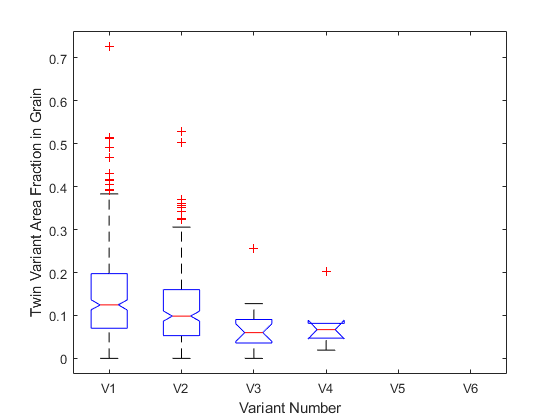

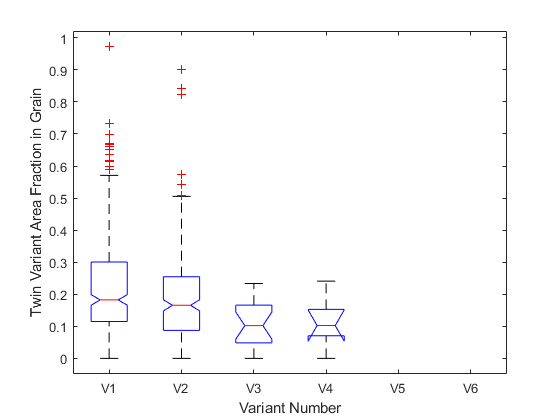

edges = 0.5:6.5;    % edges for variant [v1 - v6]
for iE = 2:5
    ind = (T2.iE==iE)&(T2.vActiveTF==1);
    t2 = T2(ind,:);
    vx = t2.variant;
    vy = t2.vPct; 
    gv = discretize(vx, edges);
    nGroups = length(edges)-1;
    clear labels;
    for ii = 1:length(edges)-1
        labels{ii} = ['V',num2str(ii)];
    end
    figure;disableDefaultInteractivity(gca);
    boxplot([vy; nan*ones(nGroups, 1)], [gv; (1:nGroups)'],'notch','on');
    xlabel('Variant Number'); ylabel(ylabel_str)
    set(gca,'xticklabels',labels);
    
end

**(1.3) We observed that, the counts of active twin variants increases with the increase of twin variant Schmid factor.**

disp(['========twin variant activated/not vs SF==============================']);

========twin variant activated/not vs SF==============================


colororder('default');

C = colororder;
C = [.5 .5 .5; 1 0 0];
edges = -0.5:0.05:0.5;
for iE=2:5
    ind = (T2.iE==iE)&(T2.vActiveTF == 1);
    ind2 = (T2.iE==iE)&(T2.vActiveTF == 0);
    [N_t,~] = histcounts(T2.variant_SF(ind), edges);
    [N_nt,~] = histcounts(T2.variant_SF(ind2), edges);
    
    figure; hold on; disableDefaultInteractivity(gca);
    hbar = bar(edges(1:end-1)+0.025, [N_nt(:), N_t(:)], 1, 'stacked');
    set(gca,'fontsize',12, 'XTick',-0.5:0.1:0.5,'ylim',[0 1600]);
    xlabel('Twin Variant Schmid Factor');
    ylabel('Counts');
    
    yyaxis right;
    set(gca, 'ycolor', 'k','fontsize',16);
    ylabel('Percent');
    plot(-0.475:0.05:0.475, N_t./(N_t+N_nt),'-ko','linewidth',1.5);

    title(['iE = ',num2str(iE)],'fontweight','normal');
    legend({'Variants not twinned', 'Variants twinned','Percent of variants twinned'},'Location','northwest');
    
%     hbar(1).FaceColor = [0 0.4470 0.7410];
%     hbar(2).FaceColor = [0.8500 0.3250 0.0980];
    hbar(1).FaceColor = [0 0 1];
    hbar(2).FaceColor = [1 0 0];

**           [5. Plot used for paper, Fig 4a]:  X = Twin Variant Schmid Factor,  Y = Counts,  YY = Percent,  for All Twin Variants**

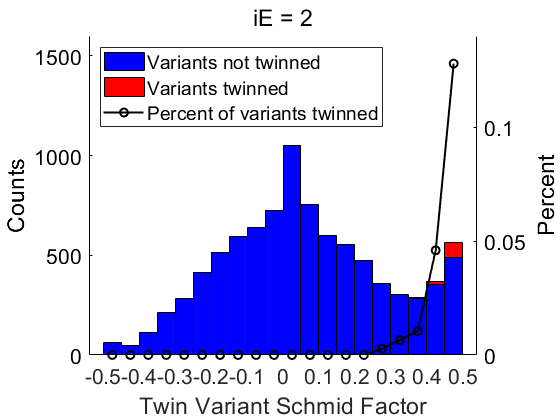

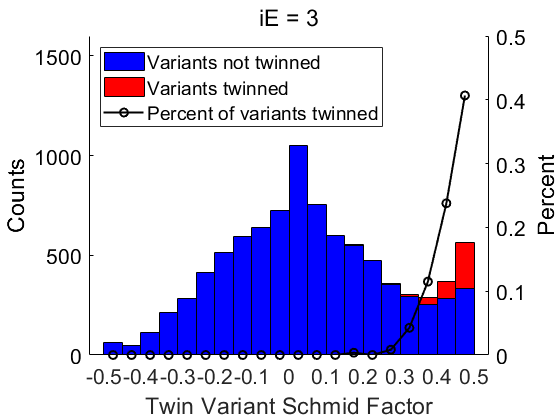

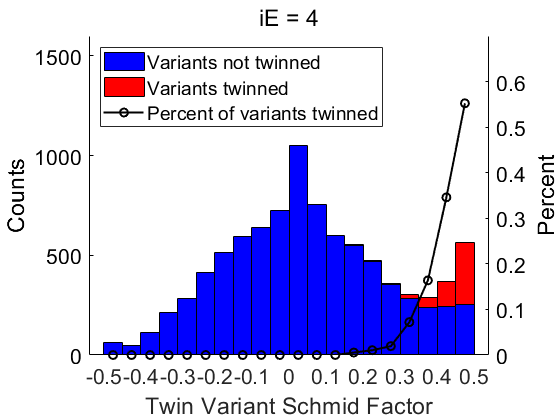

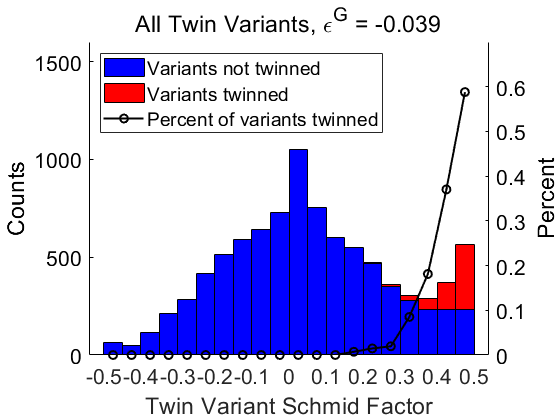

    if iE==5
        title('All Twin Variants, \epsilon^G = -0.039');
    end
end

** Summarize the ones activated at each iEs**

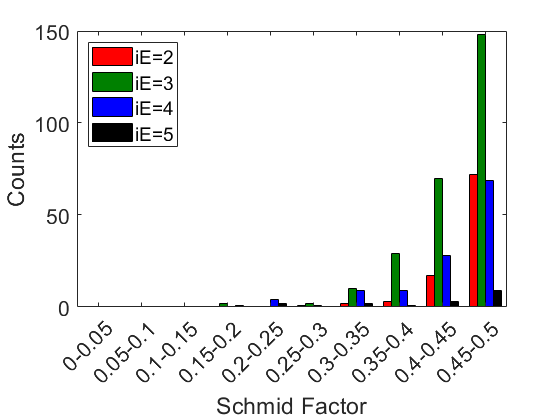

clear t Nts;
edgesT = 0:0.05:0.5;
xpos = 0.025:0.05:0.475;
for iE = 2:5
    ind = (T2.iE==iE)&(T2.vActiveTF == 1);
    t{iE} = [T2.ID(ind), T2.iTwin(ind), T2.variant_SF(ind)];
end
% loop from high to low iE, leave the unique, i.e., newly activated ones
for iE=5:-1:2
    if iE>2
        ind = ~ismember(t{iE}(:,1:2),t{iE-1}(:,1:2));
        t{iE} = t{iE}(ind,:);
    end
    Nts(iE,:) = histcounts(t{iE}(:,3), edgesT);
end
for ii = 1:length(edgesT)-1
    labels{ii} = [num2str(edgesT(ii)),'-',num2str(edgesT(ii+1))];
end
figure;disableDefaultInteractivity(gca);
co = [1 0 0; 0 0.5 0; 0 0 1; 0 0 0];
set(groot,'defaultAxesColorOrder',co);
bar(xpos, Nts(2:5,:)',1);
set(gca,'xlim',[0 0.5],'xTick',xpos,'xTickLabel',labels,'XTickLabelRotation',45,'fontsize',16);
legend('iE=2','iE=3','iE=4','iE=5','location','northwest');
xlabel('Schmid Factor');
ylabel('Counts');

set(groot,'defaultAxesColorOrder','remove');

**(1.4) For a grain, if it has high max basal SF, it is not likely to twin.**

**The plot shows: (x-axis) basal SF bins, (y-axis) counts of grains with twin (orange) without twin(blue), (yy-axis) pct of grains with twin**

disp(['========grain twinned/not vs basal SF==============================']);

========grain twinned/not vs basal SF==============================


edges = 0:0.05:0.5;
for iE=2:5
    ind1 = (T.iE==iE)&(T.twinnedTF==0);
    N_nt = histcounts(T.basal_SF(ind1), edges);
    ind2 = (T.iE==iE)&(T.twinnedTF==1);
    N_t = histcounts(T.basal_SF(ind2), edges);
    d_int = (edges(3)-edges(2))/2;
    xpos = [edges(2)-d_int, edges(2:end-1)+d_int];
    xstr = [];
    for ii=1:length(edges)-1
        xstr{ii} = [num2str(edges(ii)),'-',num2str(edges(ii+1))];
    end
    figure;disableDefaultInteractivity(gca);
    hbar = bar(xpos, [N_nt(:),N_t(:)], 1, 'stacked');
    set(gca,'ylim',[0 400]);
    xlabel('Maximum Basal Schmid Factor');
    ylabel('Counts');
    
    yyaxis right;
    set(gca,'ycolor','k','XTick',edges(1:end-1)+d_int,'xTickLabels',xstr,'xTickLabelRotation',45);
    plot(xpos, N_t./(N_t+N_nt),'-ko','linewidth',1.5);
    ylabel('Percent');
    legend('Grains not twinned','Grains twinned','Percent of grains twinned','location','northwest');
    set(gca,'fontsize',12,'ylim',[0 1.2],'fontsize',16);
    title(['Basal SF, iE = ',num2str(iE)],'fontweight','normal');
    
    hbar(1).FaceColor = [0 0 1];
    hbar(2).FaceColor = [1 0 0];
    

**            [6. Plot used for paper, Fig 4b]:  X = Maximum Basal Schmid Factor,  Y = Counts,  YY = Percent,  for All Grains**

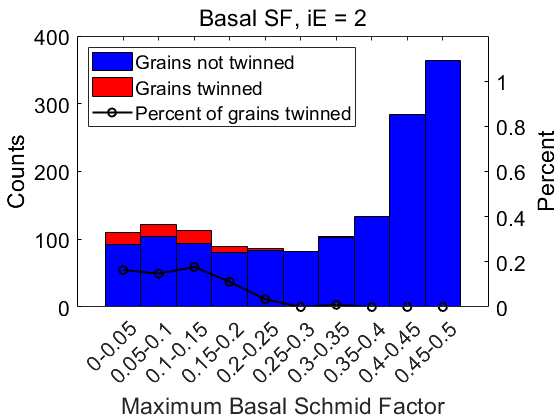

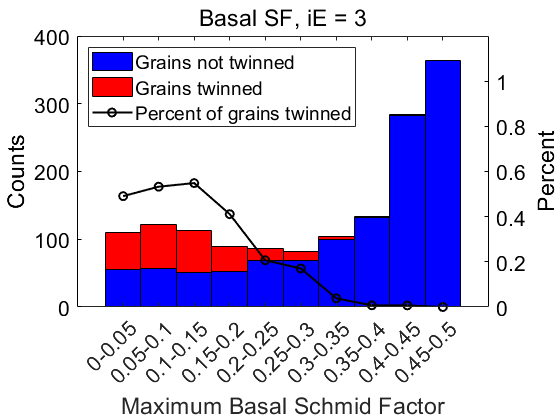

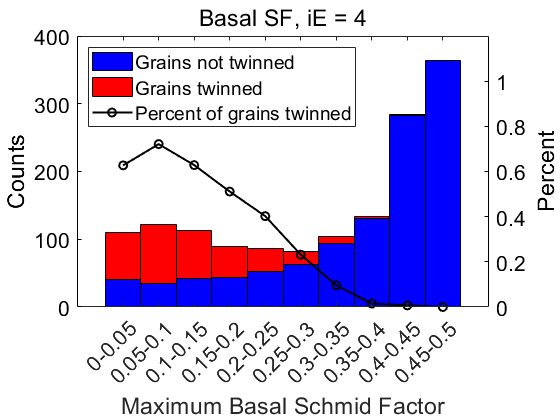

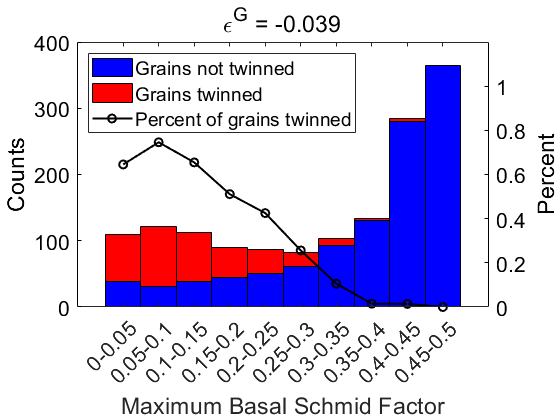

    if iE==5
        title('\epsilon^G = -0.039');
    end
end

**(1.5) This is similar way to plot as in Irene's PhiMag paper. For each grain, max basal SF vs max twin SF for grains with & without twin.**

for iE = 2:5
    figure;disableDefaultInteractivity(gca); hold on;
    ind = (T.iE==iE)&(T.twinnedTF==0);
    plot(T.twin_SF(ind), T.basal_SF(ind),'.','markersize',12,'color','b'); % '#0072BD'
    xlabel('Max Twin Schmid Factor');
    ylabel('Max Basal Schmid Factor');
    title(['iE = ',num2str(iE)],'fontweight','normal');
    legend('Not twinned','location','southwest');
    set(gca,'fontsize',16,'xTick',-0.5:0.1:0.5,'xlim',[-0.5,0.5],'ylim',[0 0.5]);
    

**           [7. Plot used for paper, Fig 4d]:  X = Maximum Basal (or Twin) Schmid Factor,  Y = Grain Average Effective Strain,  for Non-twinned Grain**

    if iE==5
        title('\epsilon^G = -0.039');
    end

    figure;disableDefaultInteractivity(gca); hold on;
    ind = (T.iE==iE)&(T.twinnedTF==1);
    plot(T.twin_SF(ind), T.basal_SF(ind),'.','markersize',12,'color','r');    % '#D95319'
    xlabel('Max Twin Schmid Factor');
    ylabel('Max Basal Schmid Factor');
    title(['iE = ',num2str(iE)],'fontweight','normal');
    legend('Twinned','location','southwest');
    set(gca,'fontsize',16,'xTick',-0.5:0.25:0.5,'xlim',[-0.5,0.5],'ylim',[0 0.5]);
    

**           [8. Plot used for paper, Fig 4c]:  X = Maximum Basal (or Twin) Schmid Factor,  Y = Grain Average Effective Strain,  for Twinned Grain**

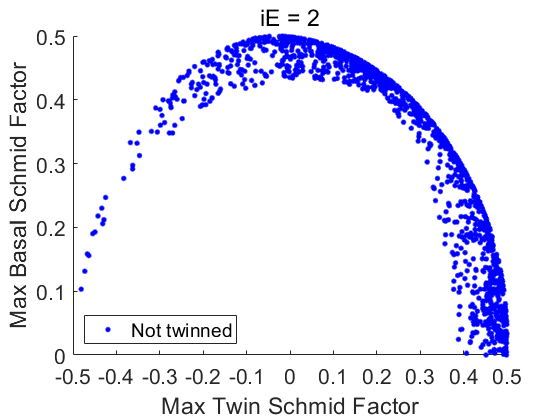

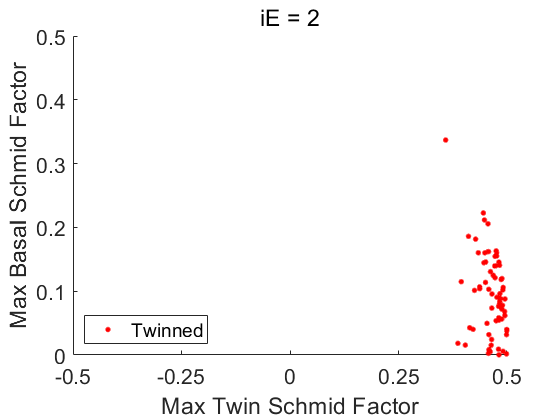

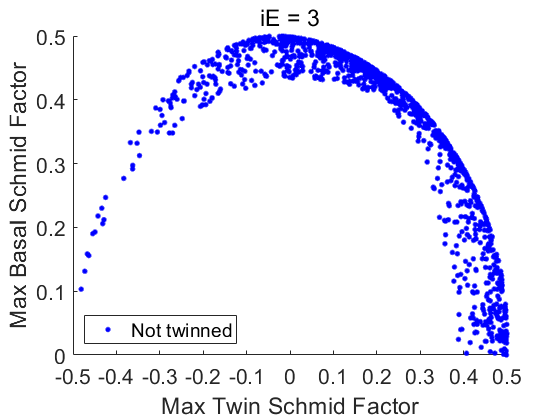

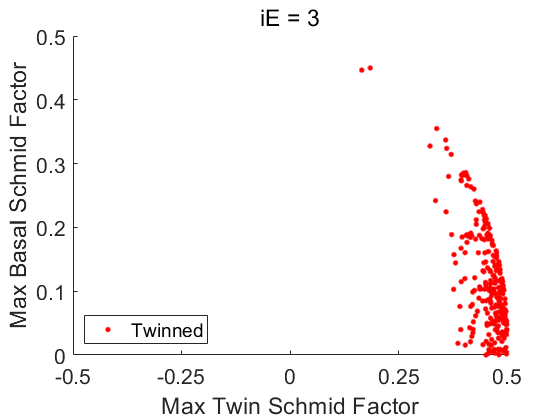

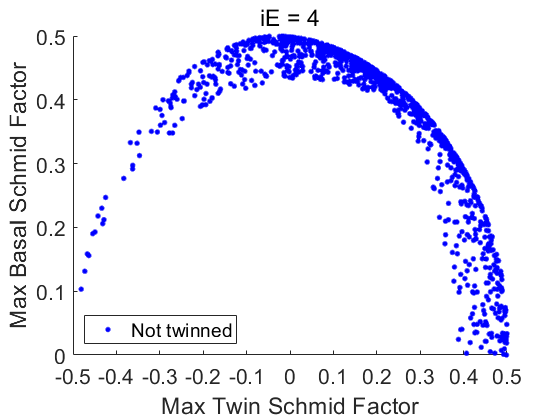

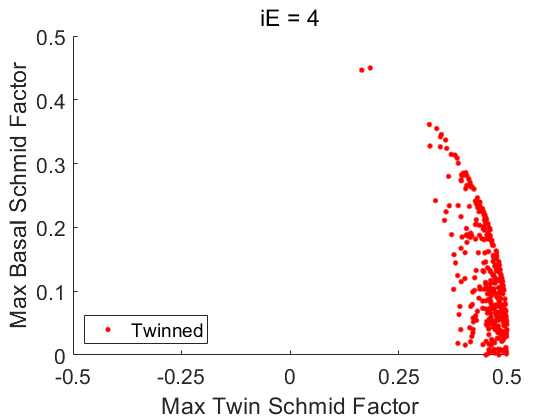

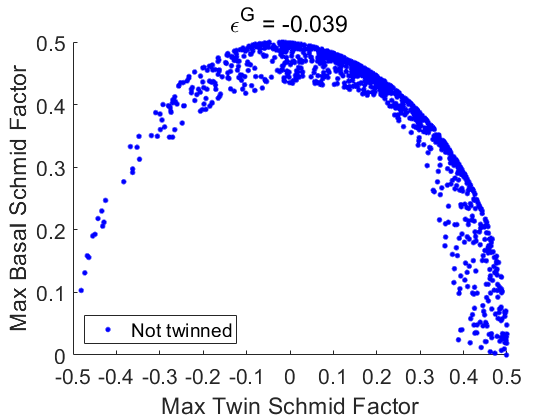

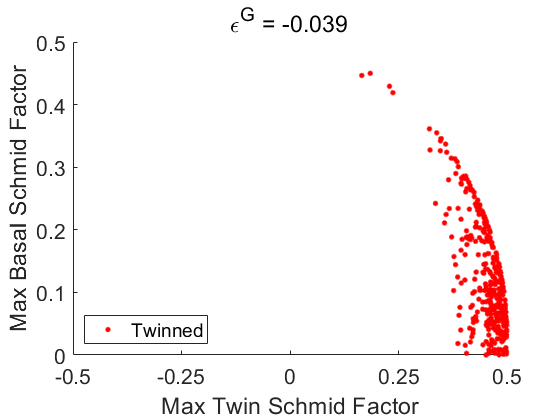

    if iE==5
        title('\epsilon^G = -0.039');
    end
end

**(2) The effect of grain size is not significant.  The counts of twinned grains slightly increase with increasing grain diameter.  But this might be an artifact, because small grains are difficult to label? **

**Overall, the twinned grains reach about 25% at iE=5, this is comparable to the 20% in Beyerlein 2010 PhilMag paper.**

disp(['========grain twinned/not vs grain size==============================']);

========grain twinned/not vs grain size==============================


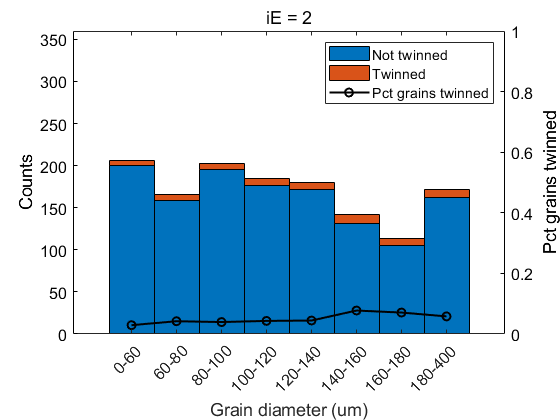

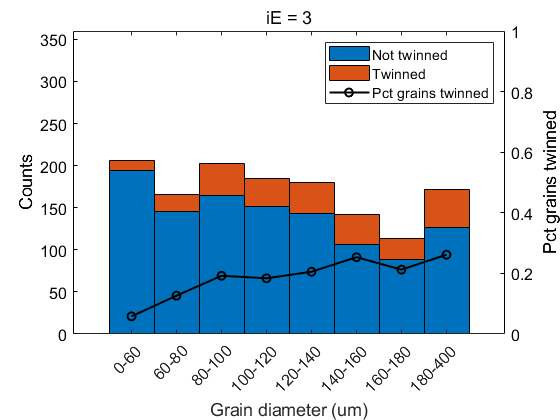

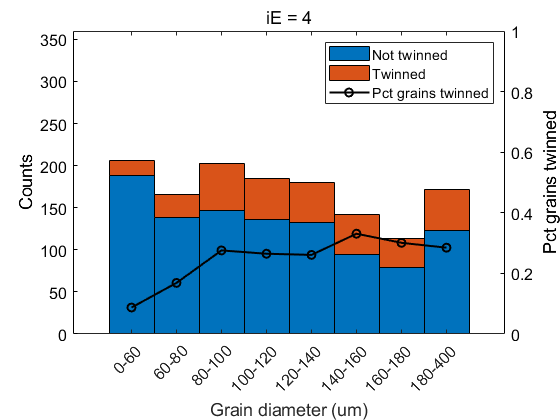

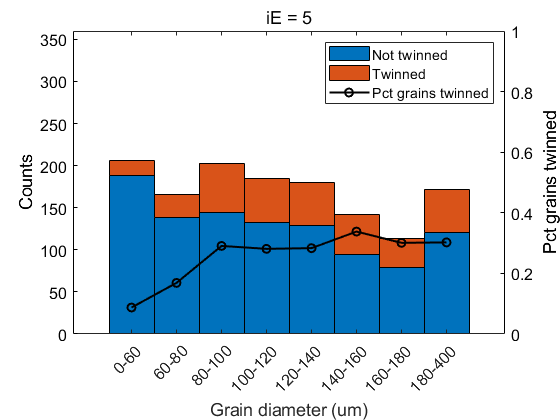

all_dia = sort(T.gDia);
inds = floor(linspace(1,length(all_dia),9));
edges_gd = all_dia(inds);
pct = [];

edges_gd =[0,60:20:180,400];
% edges_gd =[0,180,400];
for iE=2:5
    ind = (T.iE==iE)&(T.twinnedTF==1)&(~ismember(T.ID,edge_gIDs));
    [N_t,~] = histcounts(T.gDia(ind), edges_gd);
    ind2 = (T.iE==iE)&(T.twinnedTF==0)&(~ismember(T.ID,edge_gIDs));
    [N_nt,~] = histcounts(T.gDia(ind2), edges_gd);
    
    d_int = (edges_gd(3)-edges_gd(2))/2;
    xpos = [edges_gd(2)-d_int, edges_gd(2:end-1)+d_int];
    xstr = [];
    for ii=1:length(edges_gd)-1
        xstr{ii} = [num2str(edges_gd(ii)),'-',num2str(edges_gd(ii+1))];
    end
    
    figure;disableDefaultInteractivity(gca);
    hbar = bar(xpos, [N_nt(:),N_t(:)], 1, 'stacked');
    xlabel('Grain diameter (um)');
    ylabel('Counts');
    set(gca,'ylim',[0 360]);
    
    yyaxis right;
    set(gca,'ycolor','k','xTickLabels',xstr,'xTickLabelRotation',45);
    pct(iE,:) = N_t./(N_t+N_nt);
    plot(xpos, pct(iE,:),'-ko','linewidth',1.5);
    ylabel('Pct grains twinned');
    legend('Not twinned','Twinned','Pct grains twinned','location','northeast');
    set(gca,'fontsize',12,'ylim',[0 1]);
    title(['iE = ',num2str(iE)],'fontweight','normal');
    
        hbar(1).FaceColor = [0 0.4470 0.7410];
    hbar(2).FaceColor = [0.8500 0.3250 0.0980];
    
end

**[9. Plot used for paper, Fig 7a]:  X =  Grain Diameter,  Y = Pct of # of Grains Twinned**

**Combine the 4 strain levels, compare the number percentage of grains twinned.**

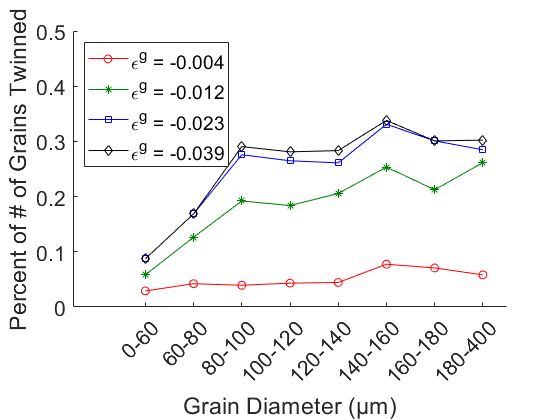

colors = [0 0 0; 1 0 0; 0 0.5 0; 0 0 1; 0 0 0];
figure;
hold on;

plot(xpos, pct(2,:), '-o','color',colors(2,:));    
plot(xpos, pct(3,:), '-*','color',colors(3,:));   
plot(xpos, pct(4,:), '-s','color',colors(4,:));   
plot(xpos, pct(5,:), '-d','color',colors(5,:));   

xlabel(['Grain Diameter (',char(181),'m)']);
ylabel('Percent of # of Grains Twinned');
legend({'\epsilon^g = -0.004','\epsilon^g = -0.012','\epsilon^g = -0.023','\epsilon^g = -0.039'},'location','northwest');
set(gca,'fontsize',16,'xlim',[20 200], 'ylim',[0, 0.5]);
set(gca,'xTick',xpos,'xTicklabel',xstr,'xTickLabelRotation',45);

**Now we use a histogram of counts of grain diameter as a background, to show how twinned area fraction changes w.r.t grain diameter.**

**The twinned area fraction in each grain seems to be decreasing with increasing grain diameter.  This might also be an artifcat, as smaller grains might have twinned areas labeled larger than it should be, due to relatively large area of noise.  **

**Note that, the notches are 95% confidence intervals of the median.  So it shows that the median is not significantly different (because notches overlap).**

**[Beyerlein 2011 PhilMag paper] derived that twin area fraction should increase with grain size, but it seems like based on an inappropriate assumption.  I have an argument.  And it maybe possible that twin area fraction should be constant, irrespect of grain size.  Assume twin thickness does not depend on grain diameter, twin density linearly depend on grain diameter (Beyerlein 2011 assume linearly depend on grain area), then the twin area fraction should be constant (Beyerlein 2011 derived linearly depend on grain diameter).**

**--> However, based on my discussion, it seems interesting and maybe necessary to use both grain-diameter and grain-area as the x-axis to examine area fraction?  Or wheter linear/area fraction should match grain diameter/area?  We can theoretically discuss ...**

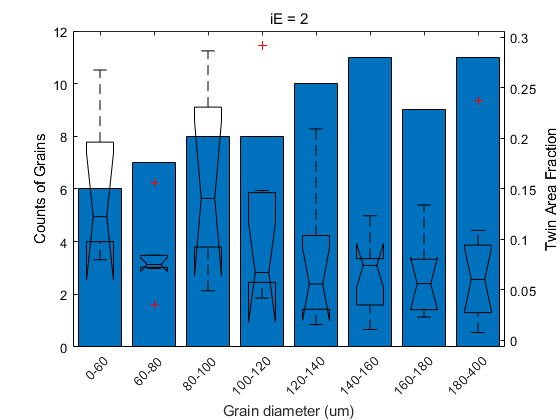

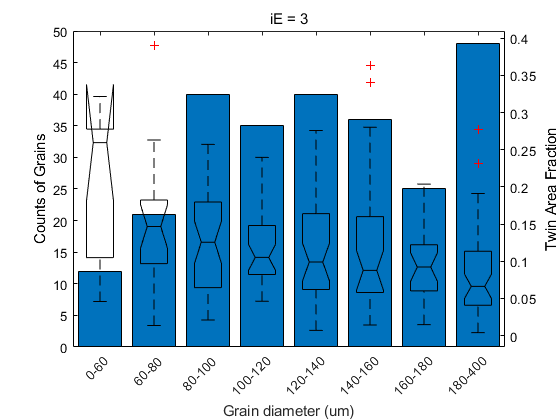

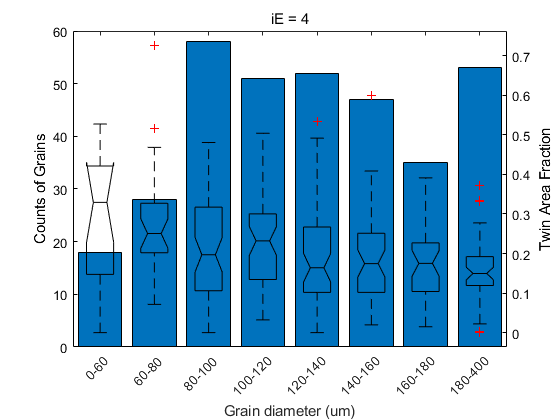

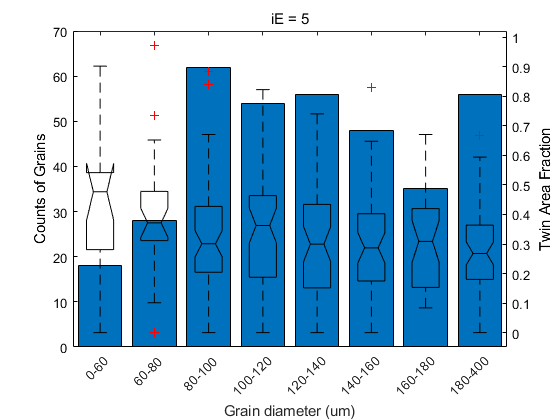

for iE=2:5
    ind = (T.iE==iE)&(T.twinnedTF==1);
    
    [N_t,~] = histcounts(T.gDia(ind), edges_gd);
    
    gDia_t = T.gDia(ind);  % (1) Use this as the grouping criterion
    tAF_t = T.tAF(ind);    % (2) This is the data to summarize the distribution, by box, in each group
    gv = discretize(gDia_t, edges_gd);  % grouping variable: grain diameter
    nGroups = length(edges_gd) - 1;
    
    figure; hold on; disableDefaultInteractivity(gca);
    hbar = bar(xpos, N_t(:));
    xlabel('Grain diameter (um)');
    ylabel('Counts of Grains');
    
    yyaxis right;
    boxplot([tAF_t;nan*ones(nGroups,1)], [gv; (1:nGroups)'], 'position', xpos,'color','k','notch','on');  % make sure every group number has a 'NaN' element
    ylabel('Twin Area Fraction');
    set(gca,'ycolor','k','xTickLabels',xstr,'xTickLabelRotation',45);
    title(['iE = ',num2str(iE)],'fontweight','normal');
    
    hbar(1).FaceColor = [0 0.4470 0.7410];
end

** [10. Plot used for paper, Fig 8b]:  X = Grain Diameter Bins,  Y = Counts,  for All Twinned Grains**

disp("=========Area twinned vs gDia, selected iE==================")

=========Area twinned vs gDia, selected iE==================


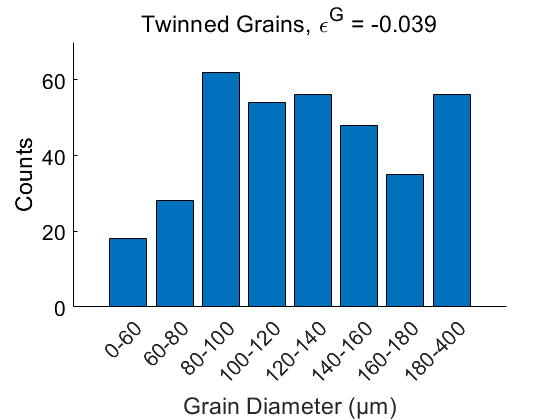

iE = 5;
ind = (T.iE==iE)&(T.twinnedTF==1);
[N_t,~] = histcounts(T.gDia(ind), edges_gd);

gDia_t = T.gDia(ind);  % (1) Use this as the grouping criterion
tAF_t = T.tAF(ind);    % (2) This is the data to summarize the distribution, by box, in each group
gv = discretize(gDia_t, edges_gd);  % grouping variable: grain diameter
nGroups = length(edges_gd) - 1;

figure; hold on; disableDefaultInteractivity(gca);
hbar = bar(xpos, N_t(:));
xlabel(['Grain Diameter (',char(181),'m)']);
ylabel('Counts');
set(gca,'ycolor','k','xTick',xpos,'xTickLabels',xstr,'xTickLabelRotation',45,'fontsize',16,'ylim',[0 70]);
title('Twinned Grains, \epsilon^G = -0.039','fontweight','normal');
hbar(1).FaceColor = [0 0.4470 0.7410];
hbar(1).FaceAlpha = 1;

** [11. Plot used for paper, Fig 8a]:  X = Grain Diameter Bins,  Y = Twin Area Fraction,  for All Twinned Grains**

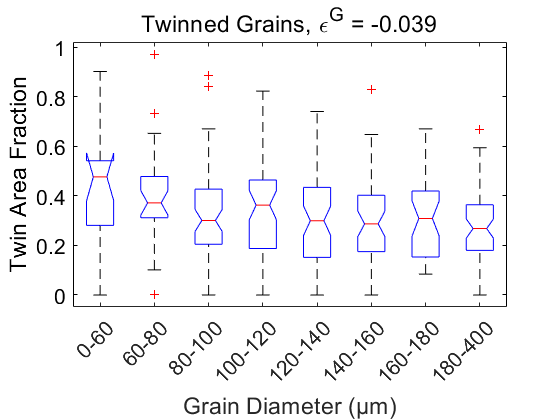

    
figure; disableDefaultInteractivity(gca);
% boxplot([tAF_t;nan*ones(nGroups,1)], [gv; (1:nGroups)'], 'position', xpos,'color','k','notch','on');  % make sure every group number has a 'NaN' element
boxplot([tAF_t;nan*ones(nGroups,1)], [gv; (1:nGroups)'], 'position', xpos,'notch','on');
xlabel(['Grain Diameter (',char(181),'m)']);
ylabel('Twin Area Fraction');
set(gca,'ycolor','k','xTickLabels',xstr,'xTickLabelRotation',45,'fontsize',16);
title('Twinned Grains, \epsilon^G = -0.039','fontweight','normal');

** [12. Plot used for paper, Fig 7b]:  Overall Grain Diameter Distribution**

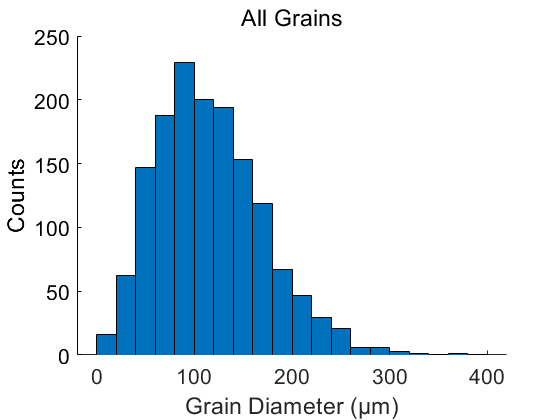

% Overal grain diameter distribution
edges_gd_all = 0:20:400;
ind = (T.iE==iE);
[N_t,~] = histcounts(T.gDia(ind), edges_gd_all);
figure; hold on; disableDefaultInteractivity(gca);
hbar = histogram(T.gDia(ind),edges_gd_all);
xlabel(['Grain Diameter (',char(181),'m)']);
ylabel('Counts');
set(gca,'ycolor','k','fontsize',16);
title('All Grains','fontweight','normal');
hbar(1).FaceColor = [0 0.4470 0.7410];
hbar(1).FaceAlpha = 1;

**[13. Plot used for paper, Fig 3a]: variant Map, zoom in strain map and variant map**

mp = variantMapCleanedCell{5};
mp(mp==0) = 0;
[f,a,c] = myplot(X,Y,mp,boundaryTFB);

matrix is big, use reduced ratio = 5


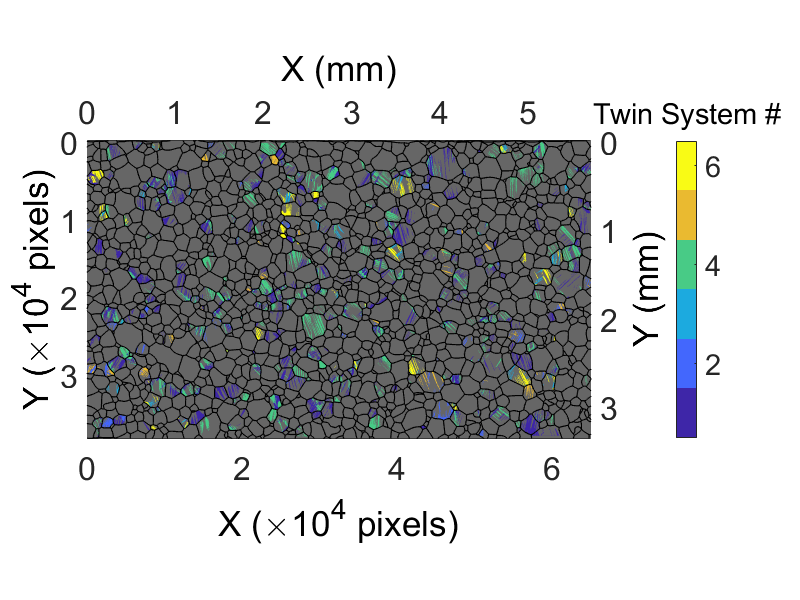

caxis([-0.5, 6.5]);
colormap([0.4 0.4 0.4; parula(6)]);
set(c,'limits',[0.5, 6.5]);

% maximize then run:
script_make_double_axis()
title(c,'Twin System #');

**So, if we consider the effect of grain size in the above two plots as an artifact, then a possible explanation might be: twins are difficult to label in small grains.  But when it does get labeled, it is likely to account for a large percentage of grain size for a small grain.**

**It's better to plot grains with diameter <80um to better visualize how they actually look.  (1) TrueTwinMap (2) Strain map**

matrix is big, use reduced ratio = 5


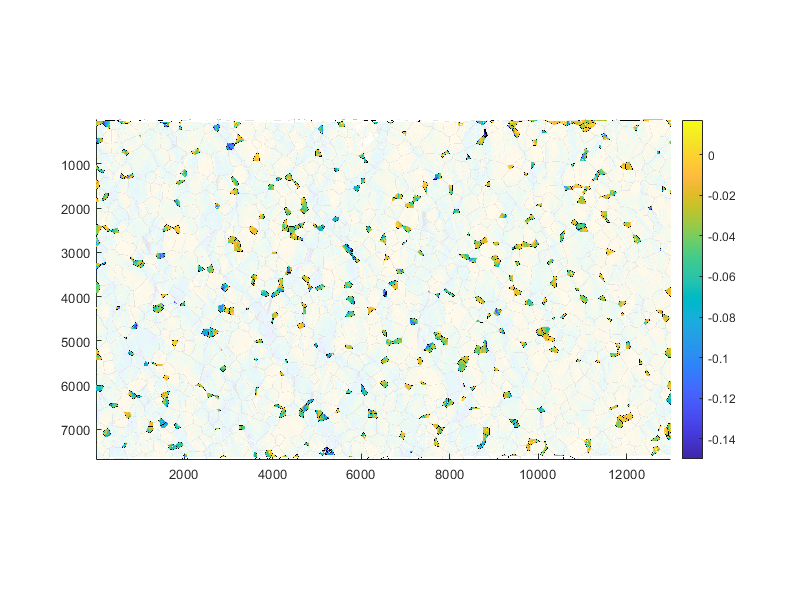

gDia_th = 80;
mask = 0.1*ones(size(ID));
list_IDs = gID(dataFile.gDiameter < gDia_th);
mask(ismember(ID,list_IDs)) = 1;

myplotm(strainFile{iE}.exx,'TF',boundaryTFB,'alpha',mask);

matrix is big, use reduced ratio = 5


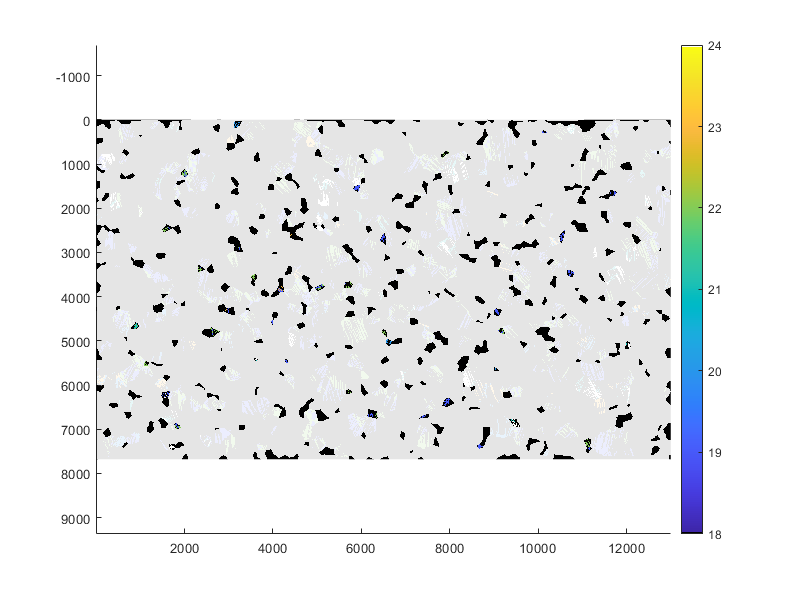


temp = trueTwinFile.trueTwinMapCell;
myplotm(temp{iE},'TF',boundaryTFB,'alpha',mask); ca([18,24]);

clear temp;
